# Week 04 - Scientific Computing fo Differential Equations

## Explicit Euler method with adaptative time step control

mu = 10;
x0 = [2.0 ; 0.0];
t0 = 0;
tN = (5*mu);
h0 = 0.0125;

abstol = 1e-7;
reltol = 1e-7;

[T,X,info] = ExplicitEulerAdaptiveStep(@VanDerPol,t0,tN,x0,h0,abstol,reltol,mu)

plot(T,X(:,1))
xlabel("t")
ylabel("x1(t)")
title("Explicit Euler with Adaptive time Step Size")

plot(T,X(:,2))
xlabel("t")
ylabel("x2(t)")

n = length(T);

plot(T(2:n),info.rr)
xlabel("t")
ylabel("r")

plot(T(2:n),info.hh)
xlabel("t")
ylabel("h")

## Runge Kutta method with adaptative time step control

mu = 10;
x0 = [2.0 ; 0.0];
t0 = 0;
tN = (5*mu);
h0 = 0.01;

abstol = 1e-12;
reltol = 1e-12;

[T,X,info] = ClassicalRungeKuttaAdaptiveStep(@VanDerPol,t0,tN,x0,h0,abstol,reltol,mu)

plot(T,X(:,1))
xlabel("t")
ylabel("x1(t)")
title("Classical Runge-Kutta with Adaptive time Step Size")

plot(T,X(:,2))
xlabel("t")
ylabel("x2(t)")

n = length(T);

plot(T(2:n),info.rr)
xlabel("t")
ylabel("r")

plot(T(2:n),info.hh)
xlabel("t")
ylabel("h")

## Implicit Euler method with adaptative time step control

mu = 10;
x0 = [2.0 ; 0.0];
t0 = 0;
tN = (5*mu);
h0 = 0.0125;

abstol = 1e-7;
reltol = 1e-7;

[T,X,info] = ImplicitEulerAdaptiveStep(@VanDerPol,t0,tN,x0,h0,abstol,reltol,mu)

info = struct with fields:
       nfun: 187811
    naccept: 93905
    nreject: 3
      nstep: 187814


T =          0
    0.0001
    0.0001
    0.0002
    0.0003
    0.0004
    0.0004
    0.0005
    0.0006
    0.0007


X =     2.0000         0
    2.0000   -0.0001
    2.0000   -0.0003
    2.0000   -0.0004
    2.0000   -0.0006
    2.0000   -0.0007
    2.0000   -0.0009
    2.0000   -0.0010
    2.0000   -0.0012
    2.0000   -0.0013


info = struct with fields:
       nfun: 187811
    naccept: 93905
    nreject: 3
      nstep: 187814
       hvec: [1×93907 double]
       rvec: [1×93907 double]
        err: [93904×2 double]
         rr: [93904×1 double]
         hh: [93904×1 double]


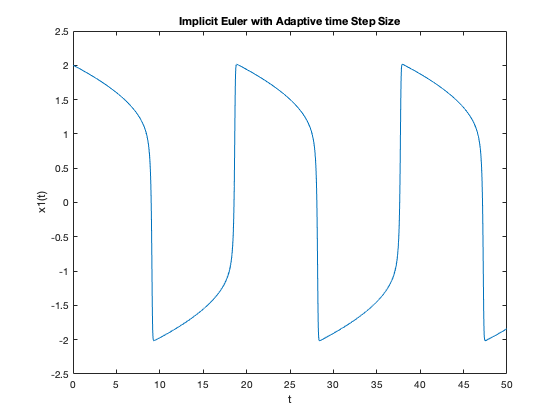

plot(T,X(:,1))
xlabel("t")
ylabel("x1(t)")
title("Implicit Euler with Adaptive time Step Size")

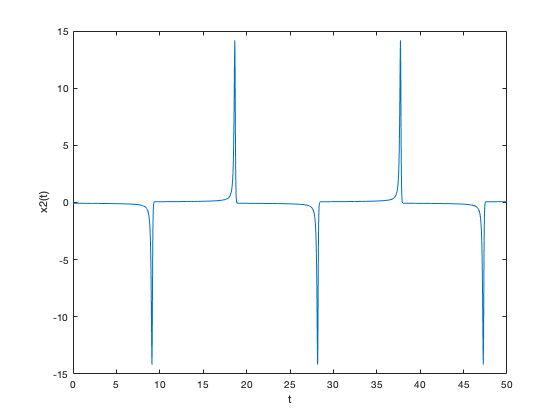


plot(T,X(:,2))
xlabel("t")
ylabel("x2(t)")

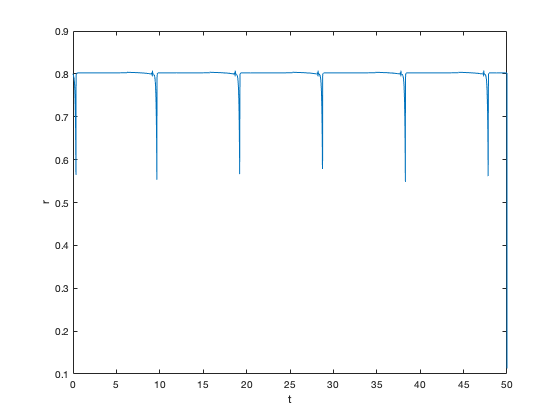


n = length(T);

plot(T(2:n),info.rr)
xlabel("t")
ylabel("r")

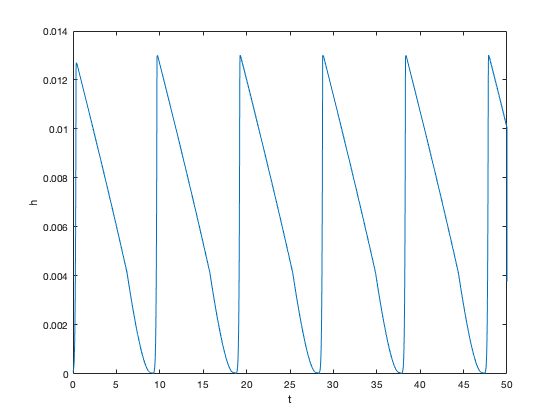


plot(T(2:n),info.hh)
xlabel("t")
ylabel("h")